# Testing Sensitivity Formula for the sAIF Controller

## Fixed Point Computation

clear
ComputeFP = @ComputeFP_sAIF_BirthDeath;

## Parameters

mu = 20;
theta = 0.4;
delta = 0.1;
eta = 0.12;
alpha = 100;
kappa = 2;
gamma_1 = 0.1;
Delta = 0.01;

## Numerical Computation of the Sensitivity

Parameters.mu = mu;
Parameters.theta = theta;
Parameters.delta = delta;
Parameters.eta = eta;
Parameters.alpha = alpha;
Parameters.kappa = kappa;
Parameters.gamma_1 = gamma_1 + Delta;

N = 100;
epsilon_vector = logspace(-5, -1, N);
Sensitivity_Numerical = zeros(N,1);
Output_Index = 1;
FP_0 = ComputeFP(Parameters);
for i = 1 : length(epsilon_vector)
    Parameters.gamma_1 = gamma_1 + Delta + epsilon_vector(i);
    FP_epsilon = ComputeFP(Parameters);
    Sensitivity_Numerical(i) = (FP_epsilon(Output_Index) - FP_0(Output_Index)) / epsilon_vector(i);
end
Sensitivity_Numerical = abs(Sensitivity_Numerical);

## Analytic Calculation of the Sensitivity

x_L = FP_0(Output_Index);
g = kappa*(alpha/((gamma_1 + Delta)*x_L) - 1);
dgdx = -kappa*alpha/(gamma_1 + Delta)/x_L^2;
dgdDelta = -kappa*alpha/x_L/(gamma_1 + Delta)^2;
Sensitivity_Analytical = abs(dgdDelta) / (abs(dgdx) + (theta/delta) / (1 + eta*mu/(eta*g + delta)^2) );

## Plot Results

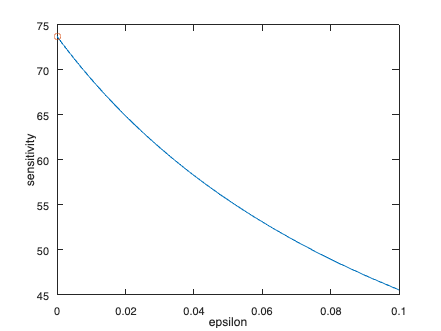

plot(epsilon_vector, Sensitivity_Numerical);
hold on
plot(0, Sensitivity_Analytical, 'o');
xlabel('epsilon');
ylabel('sensitivity')